clc
clear all
close all

E_100= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\Young_Modulus_100.txt','r');
E_200= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\Young_Modulus_200.txt','r');
E_MWCNT =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\Young_Modulus_MWCNT.txt','r');
Srate = [1 0.75 0.5 0.25]'*1e-3 ;

Modu100 = [cell2mat(textscan(E_100,'%f%f%f%f'))]*1e-3 

Modu100 =   534.2187  534.5604  550.3976  539.9229
  371.4551  375.5941  375.4032  378.9402
  263.6480  272.0700  279.9661  278.6031
  233.1170  228.7325  213.2242  226.2577


Modu200 = [cell2mat(textscan(E_200,'%f%f%f%f'))]*1e-3     %300K,800k,1000k,2400k

Modu200 =   373.2726  303.1096  353.1689  364.6736
  307.4897  305.7396  306.7385  306.4814
  237.8940  248.2477  248.8561  246.0054
  213.8799  209.7034  204.4577  214.7716


Modumwcnt = [cell2mat(textscan(E_MWCNT,'%f%f%f%f'))]*1e-3     %in Gpa

Modumwcnt =   437.9939  396.2270  429.8028  429.7392
  340.6364  377.8655  373.8162  387.3412
  342.5606  329.6186  321.7610  327.1203
  336.0329  342.4468  338.0611  340.3030


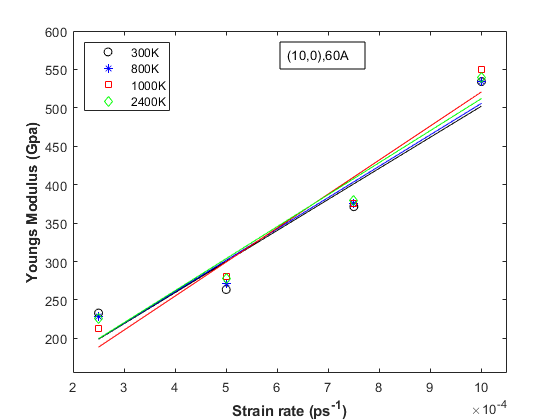



fclose(E_200);fclose(E_MWCNT);fclose(E_100);


%%%%% make sure upto wichh part linearity follos
g1 = fit(Srate,Modu100(:,1),'poly1') ; %300k
g2 = fit(Srate,Modu100(:,2),'poly1') ;
g3 = fit(Srate,Modu100(:,3),'poly1') ;
g4 = fit(Srate,Modu100(:,4),'poly1') ;
f1 = fit(Srate,Modu200(:,1),'poly1') ; %300k
f2 = fit(Srate,Modu200(:,2),'poly1') ; %800K
f3 = fit(Srate,Modu200(:,3),'poly1') ; %100k
f4 = fit(Srate,Modu200(:,4),'poly1') ;     %2400k
f1m = fit(Srate,Modumwcnt(:,1),'poly1') ; %300k MWCNT
f2m = fit(Srate,Modumwcnt(:,2),'poly1') ;     %
f3m = fit(Srate,Modumwcnt(:,3),'poly1') ;
f4m = fit(Srate,Modumwcnt(:,4),'poly1') ;     %2400k


figure(1)   %swcnt (10,0)
plot(g1,'-k',Srate,Modu100(:,1),'ok');  hold on 
plot(g2,'-b',Srate,Modu100(:,2),'*b');  hold on 
plot(g3,'-r',Srate,Modu100(:,3),'sr');  hold on 
plot(g4,'-g',Srate,Modu100(:,4),'dg');  hold on 

xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Youngs Modulus (Gpa)',"FontWeight","bold")
legend('300K','','800K','','1000K','','2400K','','Location','northwest')
annotation('textbox', [0.5, 0.8, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Young_modulus10060A.jpg')

xlim([0.0002 0.00105])
ylim([155 600])

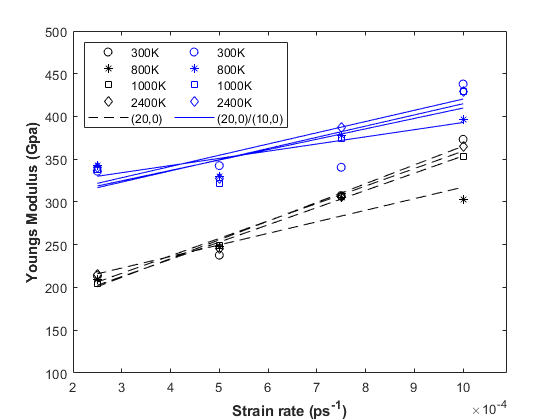


figure(2);  %20,0 20,0+10,0
plot(f1,'--k',Srate,Modu200(:,1),'ok');  hold on 
plot(f2,'--k',Srate,Modu200(:,2),'*k');  hold on 
plot(f3,'--k',Srate,Modu200(:,3),'sk');  hold on 
plot(f4,'--k',Srate,Modu200(:,4),'dk');  hold on 

plot(f1m,'-b',Srate,Modumwcnt(:,1),'ob');   hold on 
plot(f2m,'-b',Srate,Modumwcnt(:,2),'*b');   hold on 
plot(f3m,'-b',Srate,Modumwcnt(:,3),'sb');   hold on 
plot(f4m,'-b',Srate,Modumwcnt(:,4),'db');   hold on 


xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Youngs Modulus (Gpa)',"FontWeight","bold")

legend('300K','','800K','','1000K','','2400K','(20,0)','300K','','800K','','1000K','','2400K','(20,0)/(10,0)','Location','northwest','NumColumns',2)

xlim([0.0002 0.00109])
ylim([100 500])
%annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Young_modulus200100.jpg')
 hold off

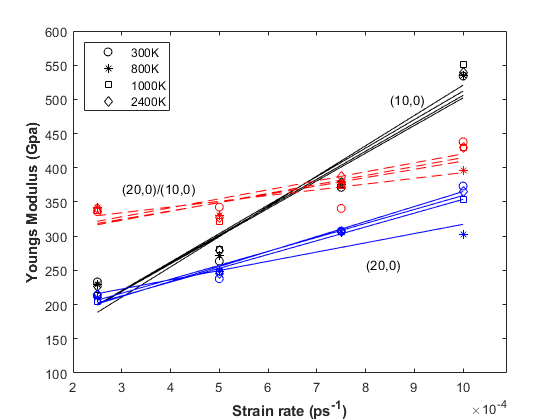

%%% alll combine

figure(3)
plot(g1,'-k',Srate,Modu100(:,1),'ok');  hold on 
plot(g2,'-k',Srate,Modu100(:,2),'*k');  hold on 
plot(g3,'-k',Srate,Modu100(:,3),'sk');  hold on 
plot(g4,'-k',Srate,Modu100(:,4),'dk');  hold on 

plot(f1,'-b',Srate,Modu200(:,1),'ob');  hold on 
plot(f2,'-b',Srate,Modu200(:,2),'*b');  hold on 
plot(f3,'-b',Srate,Modu200(:,3),'sb');  hold on 
plot(f4,'-b',Srate,Modu200(:,4),'db');  hold on 

plot(f1m,'--r',Srate,Modumwcnt(:,1),'or');   hold on 
plot(f2m,'--r',Srate,Modumwcnt(:,2),'*r');   hold on 
plot(f3m,'--r',Srate,Modumwcnt(:,3),'sr');   hold on 
plot(f4m,'--r',Srate,Modumwcnt(:,4),'dr');   hold on 


xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Youngs Modulus (Gpa)',"FontWeight","bold")
text(0.00085,500,'(10,0)')
text(8e-4,260,'(20,0)')
text(3e-4,370,'(20,0)/(10,0)')

legend('300K','','800K','','1000K','','2400K','','','','','','','','','','','','','','','','','','Location','northwest','NumColumns',1)
% 
xlim([0.0002 0.00109])
ylim([100 600])
% %annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Young_moduluCompaAll.jpg')
 hold off